# X.X.XX. Быстрое преобразование Фурье

Преобазование Фурье - вид интегрального преобразования, широко использующегося во многих областях науки. Понятие преобразования Фурье тесно связано с определением ряда Фурье, а точнее с возможностью разложения периодической функции в ряд Фурье. По сути, любую периодическую функцию можно представить суперпозицией элементов ряда Фурье - гармонических колебаний с целыми частотами. Преобразование Фурье есть обобщение разложения функций в ряд. Если мы говорим об обработке сигналов, то в этом случае разложение ставит в соответствие фунции во временной области её описание в частотной области - спектр. Именно с этой позиции мы и будем рассматривать применение преобразования Фурье.

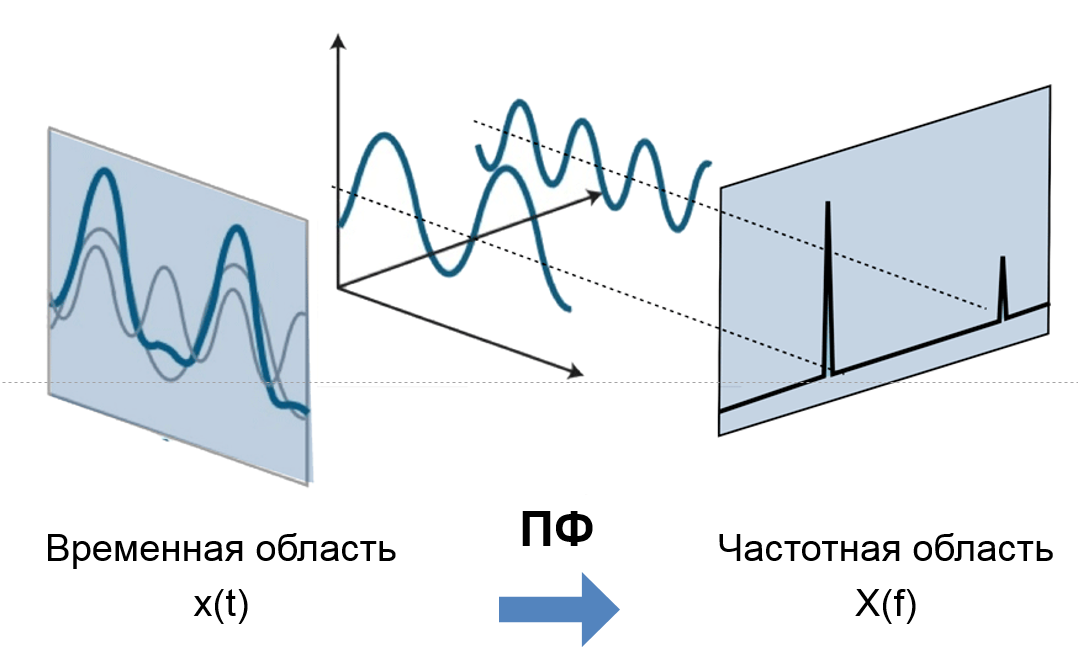

Когда мы рассматриваем дискретные последовательности, мы говорим о дискретном преобразовании Фурье (ДПФ). Формула, приведённая ниже, позволяет нам из дискретных отсчётов сигнала во временной области получить дискретные комплексные отсчёты спектра сигнала, то есть представления его в частотной области.

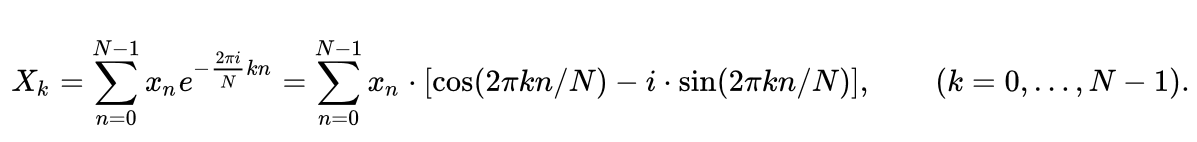

Но вычисление ДПФ по данной формуле требует большого числа арифметических операций. Быстрое преобразование Фурье (БПФ) - это эффективный алгоритм вычисления дискретного преобразования Фурье. В основе алгоритма БПФ лежит принцип "прореживания", или разделения отсчётов входного сигнала на две половины, и вычисления ДПФ для каждой из половин. Затем каждую из половин также можно разделить на две части. 

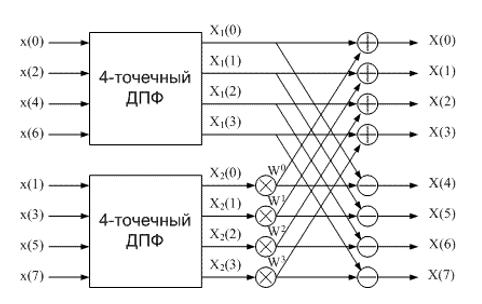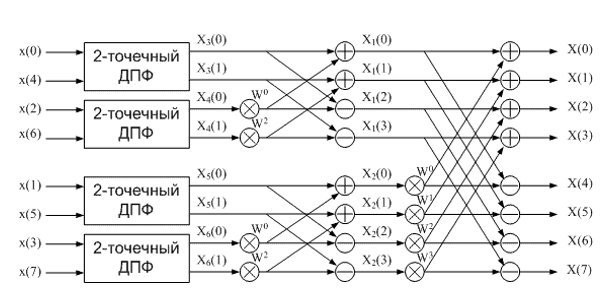

В том случае, когда число элементов входного дискретного сигнала соответствует степени двойки (64, 128, 512, 1024 и т.д.), прореживание может быть сведено к вычилению ДПФ по двум точкам. Двуточечный ДПФ называется "бабочкой по основанию 2". Существуют также варианты вычисления "бабочек" по основанию 4 и 8, но они требуют умножения на значения комплексной амплитуды, отличные от +1 и -1. А в случае двуточечного ДПФ, вычисления представляют собой просто операции суммирования и вычитания входных отсчётов.

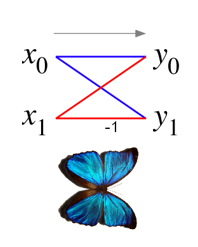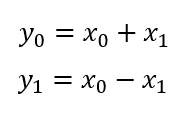

Быстрое преобразование Фурье (БПФ) в связке с обратным быстрым преобразованием Фурье (ОБПФ) повсеместно применяется для задач цифровой обработки сигналов (ЦОС), так как позволяют эффективно переносить сигналы из временной области в частотную и обратно. Анализ сигналов в частотной области осуществяется для оценки тех параметров сигнала, которые невозможно оценить во временной области. И в некоторых случаях обработка сигнала в частотной области представляет собой более простую вычислительную задачу.

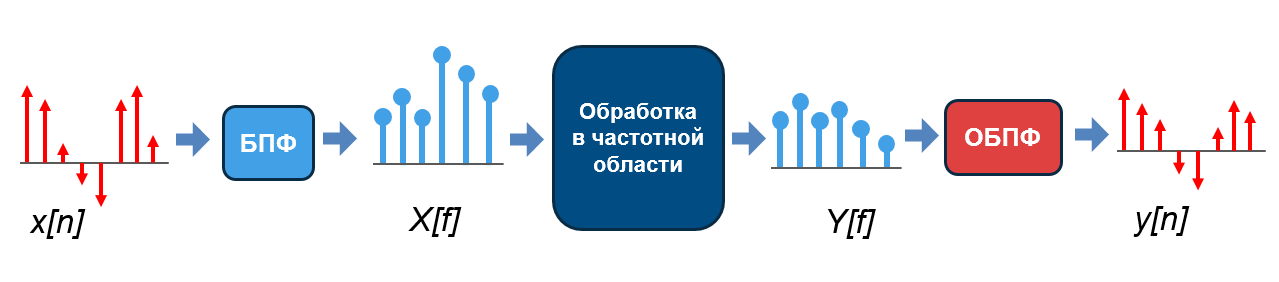

Рассмотрим пример оценки спектра аудио-файла при помощи быстрого преобразования Фурье в MATLAB. Для этого мы будем использовать встроенную функцию **fft**.

## Импорт аудио-файла в MATLAB

Считаем аудио-файл *energy.mp3* в рабочее пространство командой *audioread*. Отсчёты сигнала поместим в переменную *x*, а значение частоты дискретизации - в переменную *fs*.

[x,fs] = audioread('energy.mp3');

Ограничим число точек нашего сигнала таки образом, чтобы мы могли эффективно применить алгоритм БПФ.

x = x(1:2^18);

Прослушаем импортированный и обрезанный сигнал командой *sound, *а также отразим его во временной области.

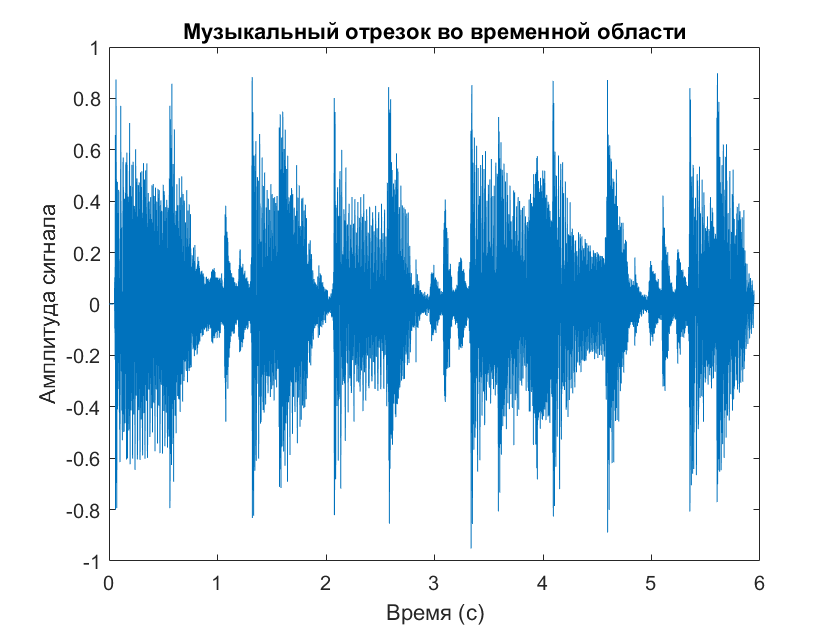

dt = 1/fs;
t = 0:dt:((2^18*dt) - dt);
t = t';
plot(t,x)
title('Музыкальный отрезок во временной области')
xlabel('Время (с)')
ylabel('Амплитуда сигнала')

sound(x,fs);

## Быстрое преобразование Фурье

Воспользуемся встроенной функцией **fft **для вычисления спектра нашего музыкального отрезка. Попробуем отразить спектр на грфике командой *plot*. 

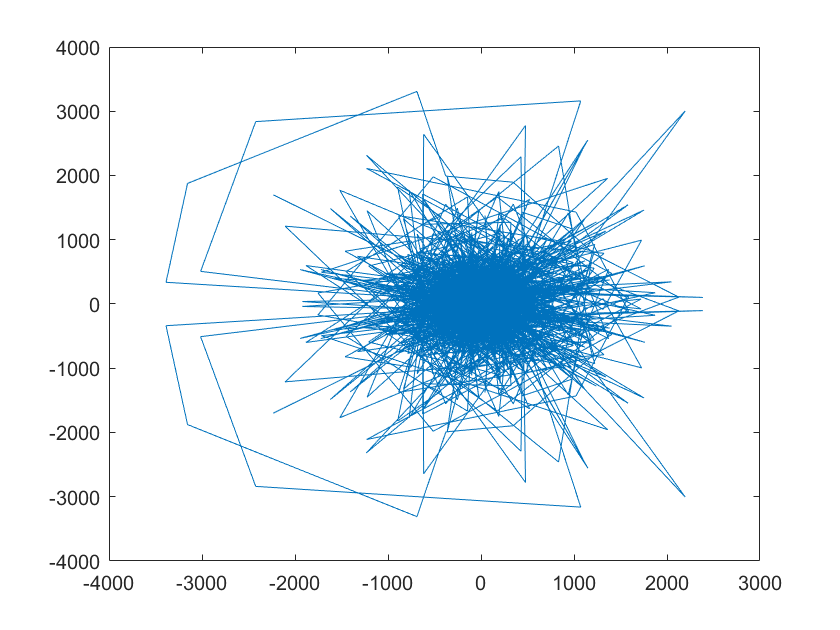

X = fft(x);
plot(X);

Полученный вектор X состоит из комплексных величин. Отсюда и такой сид графика. Звёздоподобная картинка отражается на комплексной плоскости. Связанно это с тем, что частотное представление сигнала хранит в себе не только информацию об амплитудах отдельных частотных компонент (гармоник), но также и о фазах каждой из них. Если рассматривать синусоиду на комплексной плоскости, то там она описывается вектором в полярных координатах. Длина вектора отражает амплитуду колебания, а угол, на который вектор отклоняется относитьельно действительной оси - фазу.

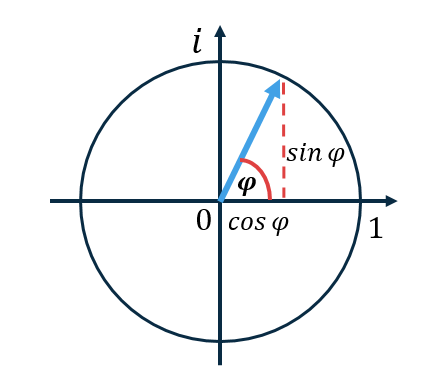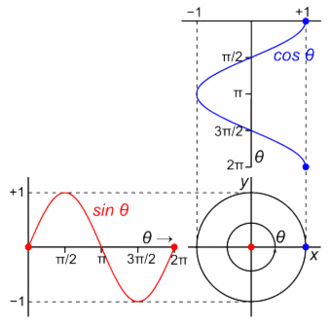

Если из полярных координат на комплексной плоскости перейти к Декартовым - мы получим комплексное представление колебания. Действительная часть - это положение точки на действительной оси х, минмая - положение на мнимой оси у. Из комплексного предстваления несложно перейти обратно к понятиям амплитуды и фазы.

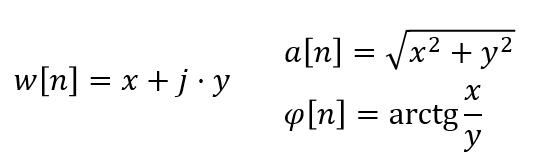

Для нашей задачи нам достаточно оценить амплитудный спектр сигнала. А как мы знаем, значения амплитуды содержатся в модуле наших комплексных отсчётов. Поэтому воспользуемся функцией *abs*:

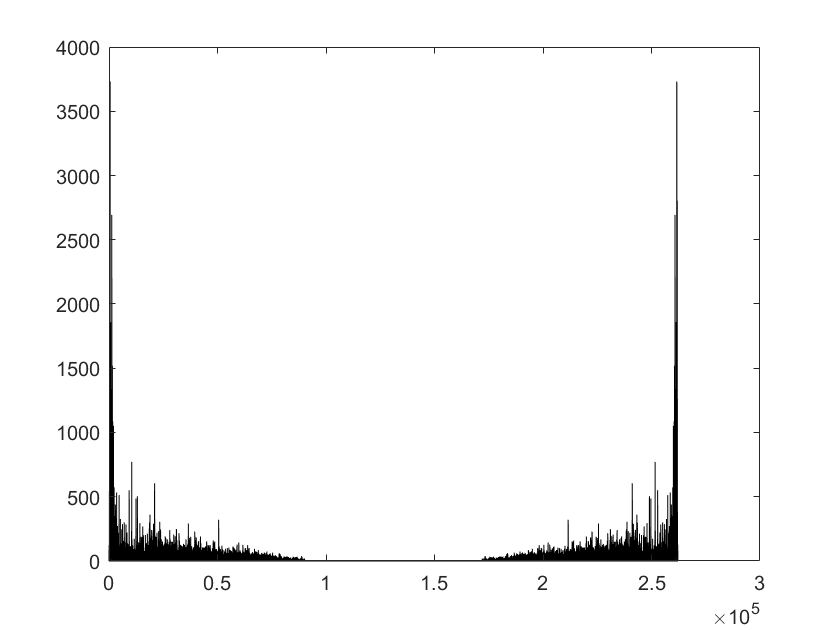

Aspectrum = abs(X);
area(Aspectrum);

Мы наблюдаем симметричную картину. Связанно это с тем, что спектр вещественного сигнала всегда симметричен отсноительно нулевой частоты, т.е. содержит компоненты с отрицательными частотами. Это оосбенность предстваления действительного колебания на компексной плоскости. Действительную синусоиду можно описать суммой двух комплексных синусоид, вращающихся в противоположных направлениях таким образом, что их сумма никогда не будет иметь мнимой составляющей. А вращение по часовой стрелке на комплексной плоскости соответствует так называемой отрицательной частоте.

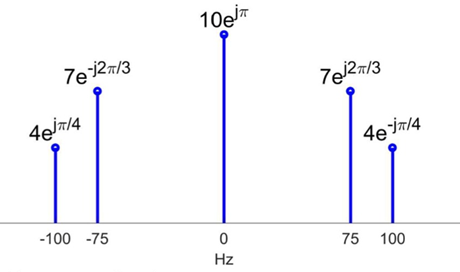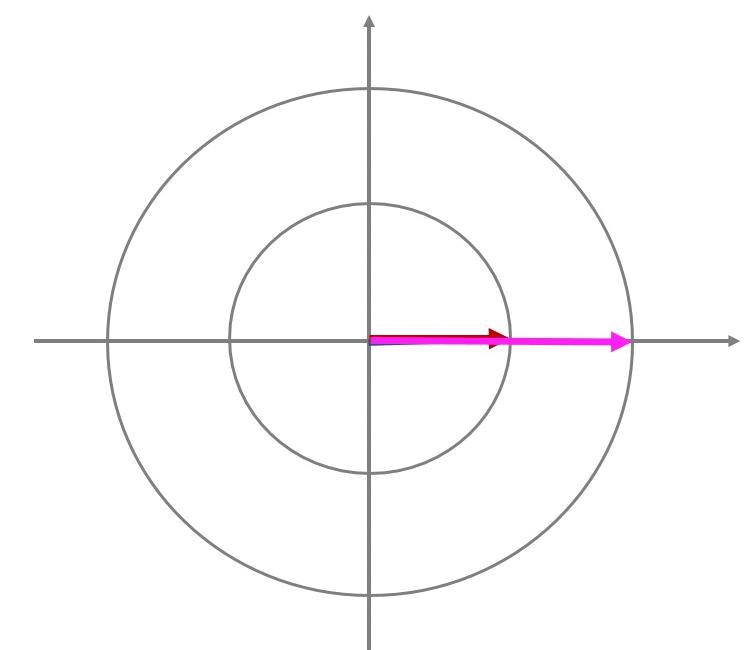

Для анализа нам не так важно наблюдать область отрицательных частот, поэтому рассмотрим только первую половину выходного вектора *X*. Отразим спетр в пределах от 0 до 10 КГц.

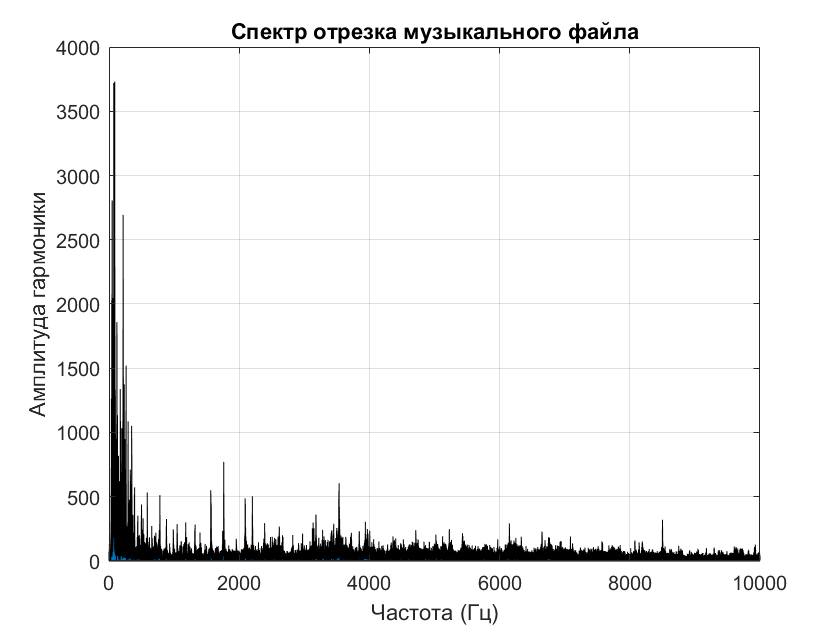

Xpositive = X([1:length(X)/2]);
Fpositive = linspace(0,fs/2,length(Xpositive));
area(Fpositive,abs(Xpositive));
xlim([0 10e3]);
grid on
title('Спектр отрезка музыкального файла')
xlabel('Частота (Гц)')
ylabel('Амплитуда гармоники')

Восстановим сигнал при помощи обратного БПФ и прослушаем его командой* sound*.

y = ifft(X);
sound(y,fs);